# Using gamma-like transients

Let the function $\gamma \left(t\right)=te^{1-t}$, looking only at positive $t$:

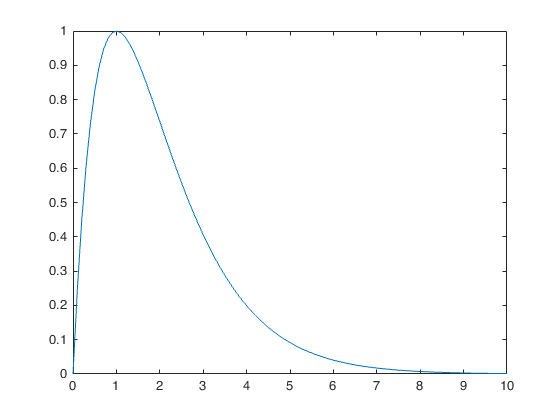

gamma = @(t) t.*exp(1-t);

t = 0:0.1:10;
figure ;
plot(t, gamma(t));

To fit this form into 0.5s at 20Hz, we will sample it at 0.5:0.5:5. There is no point in using 0, since the value is 0, and at 5 it is already below 0.1, 10 times smaller than the peak.

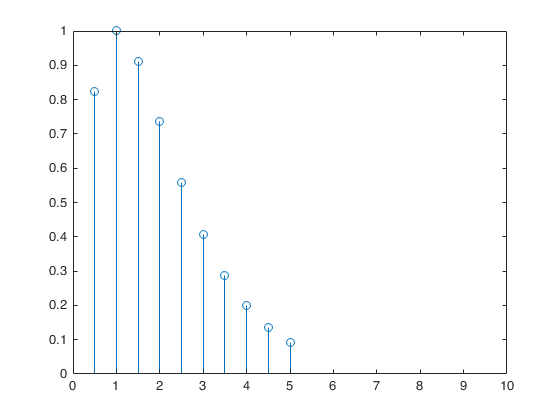

t = 0.5:0.5:5;
figure;
stem(t, gamma(t));
xlim([0 10]);

If we would like to test longer or shorter transients, we can simply scale the above:

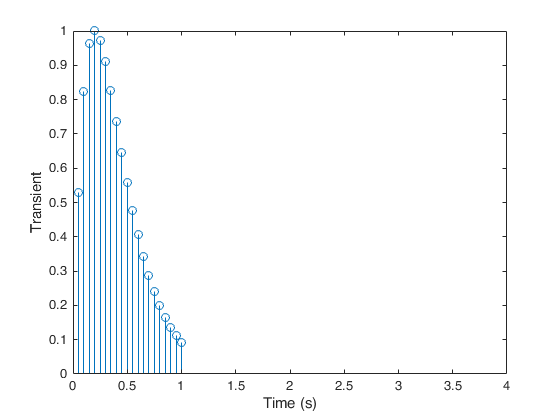

T = 1;
Fs = 20;
gamma_sample_times = linspace(0,5,T * Fs + 1);
gamma_sample_times = gamma_sample_times(2:end);
gamma_values = gamma(gamma_sample_times);

t = 1/Fs:1/Fs:T;
figure;
stem(t, gamma_values);
xlim([0 4]);
xlabel 'Time (s)'
ylabel 'Transient'